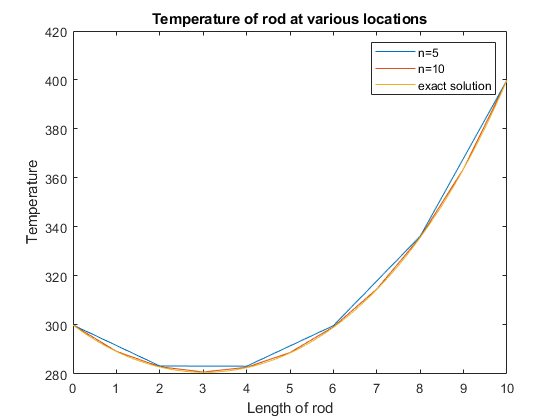

N= [5; 10];

[T1,t1] = BVPSolver(N(1));
[T2,t2] = BVPSolver(N(2));
t3 = 0:10/10^6:10;
T3 = 200 + 20.4671*exp(sqrt(0.05)*t3) + 79.5329*exp(-1*sqrt(0.05)*t3);

figure

plot(t1,T1);
hold on
plot(t2,T2);
hold on
plot(t3,T3);
title('Temperature of rod at various locations')
xlabel('Length of rod')
ylabel('Temperature')
legend('n=5','n=10','exact solution')

function [T, t] = BVPSolver(N)
    v = ones(1,N-2);
    v = v/(10/N)/(10/N);

    w = ones(1,N-1);
    w = -2*w/(10/N)/(10/N) - 0.05;

    A = diag(w,0) + diag(v,-1) + diag(v,1);

    b = ones(N-1,1);
    b(1) = -1/(10/N)/(10/N)*300 - 0.05*200;
    b(2:N-2) = -0.05*200;
    b(N-1) = -1/(10/N)/(10/N)*400 - 0.05*200;

    SOL = A\b;
    
    T = ones(N+1,1);
    T(1) = 300;
    T(2:N) = SOL;
    T(N+1) = 400;
    
    t = 0:10/N:10;
end